Siganl - CA1 - MohammadFarrahi 810198451

Problem 1

One :

The implementation of myConv is at end of the file.

a = ones(1,4);
b = ones(1,4);
z1 = conv(a,b)

z1 =      1     2     3     4     3     2     1


z2 = myConv(a,b)

z2 =      1     2     3     4     3     2     1


as you can see our function works fine.

Two :

%creating random vectors
rng('default');
random_vectors = zeros(200, 10000);
for i = 1:200
    random_vectors(i,:) = randi(30, 1, 10000);
end
% time exe measurement of myConv
myConv_time = zeros(1,100);
for i = 1:100
    tic;
    z = myConv(random_vectors(i,:), random_vectors(i+100,:));
    myConv_time(i) = toc;
end

Three :

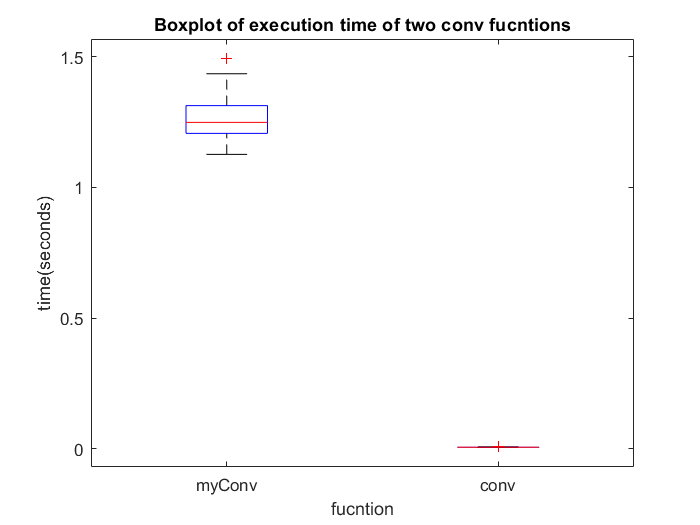

% time exe measurement of conv
conv_time = zeros(1,100);
for i = 1:100
    tic;
    z = conv(random_vectors(i,:), random_vectors(i+100,:));
    conv_time(i) = toc;
end
% plotting
boxplot([reshape(myConv_time,[],1) reshape(conv_time,[],1)], 'Labels', {'myConv', 'conv'})
title('Boxplot of execution time of two conv fucntions')
xlabel('fucntion')
ylabel('time(seconds)')

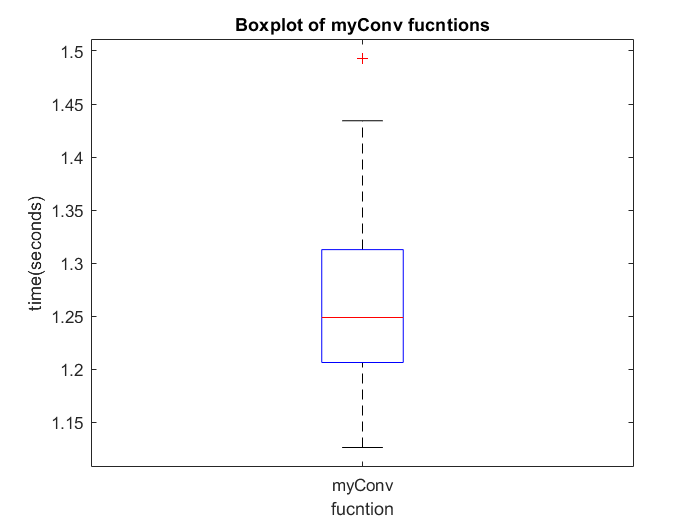

boxplot(reshape(myConv_time,[],1), 'Labels', {'myConv'})
title('Boxplot of myConv fucntions')
xlabel('fucntion')
ylabel('time(seconds)')

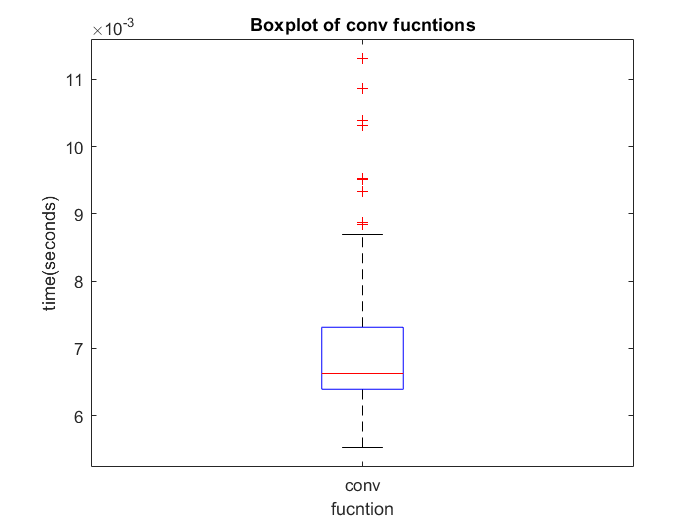

boxplot(reshape(conv_time,[],1), 'Labels', {'conv'})
title('Boxplot of conv fucntions')
xlabel('fucntion')
ylabel('time(seconds)')

as we can see in figures, obviously matlab's conv fucntion is much faster than our fucntion. It seems that that's because we didnot use vectorization and used for loops in our implementation.

Problem 2

load ecg.mat

One :

Since sampling frequency is 1000Hz, then smapling period is 0.001 seconds. For changing x-axis scale to time, we simply achieve t, by mutiplying sample numbers to sampling period and plot ECG based on new scale(t) 

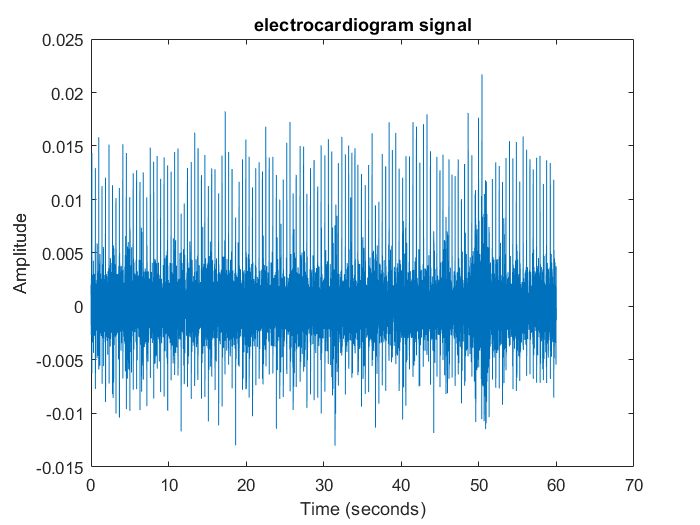

T = 0.001; % sampling period(s)
n = 1:length(ecg); % sample numbers
t = n*T;
plot(t, ecg)
xlabel('Time (seconds)')
ylabel('Amplitude')
title('electrocardiogram signal')

Two :

We choose threshold to be 0.012 and find index of values that more than that threshold. Then we declare new matrix which number of rows are equal to length of these indexs, and number of columns are equal to 100+1+200(100 values perior and itself and 200 values after). For each index, we add a row with specified values as mentioned in problem description.(100 values perior and itself and 200 values after)

threshold = 0.012;
[pks, threshold_inds] = findpeaks(ecg, 'MinPeakHeight',threshold);

new_ecg = zeros(length(threshold_inds),100+1+200);
for ind = 1:length(threshold_inds)
    new_ecg(ind,:) = reshape(ecg(threshold_inds(ind)-100:threshold_inds(ind)+200),1,[]);
end

Three :

As in part one, for ploting, we use plot function and plot each row in addition to plotting the average signal ( the one which is red)

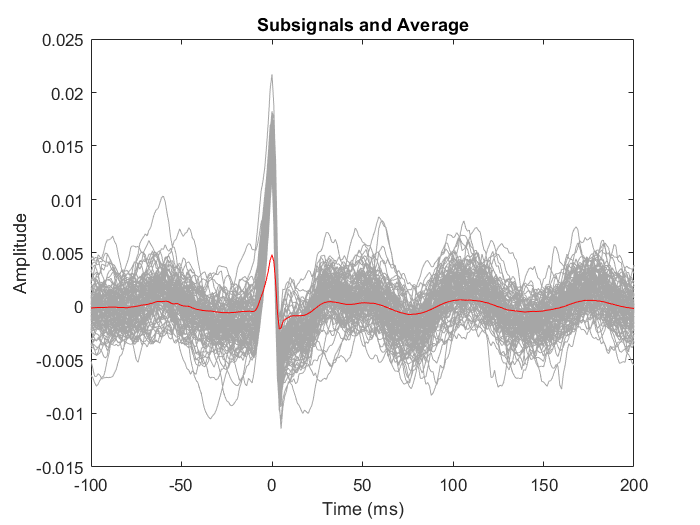

T = 1; % sampling period(ms)
n = -100:200; % sample numbers
x = n*T;
average_values_of_rows = sum(new_ecg,1)/length(new_ecg(1,:));
plot(x, new_ecg, 'Color', [0.65,0.65,0.65])
hold on
plot(x, average_values_of_rows, 'r');
xlabel('Time (ms)');
ylabel('Amplitude');
title('Subsignals and Average');
hold off;

Problem 3

One :

[voice, sampling_freq] = audioread('voice.m4a');
voice = voice(:, 1); % we use only one audio channel

Two :

the definition of system is at end of the file

T = seconds(1/sampling_freq); %sampling period
T = time2num(T, 'seconds'); %sampling period in number
n0 = floor(0.5/T) % calculating n0 to be equevalent of 0.5 seconds

n0 = 22050

alpha = 0.5

alpha = 0.5000

Three :

% Linear
x1 = 1:5;
x2 = ones(1,5);
a = 2; b = 3;
temp_alpha = 2; temp_n0 = 3;
y1 = myEcho(x1, temp_alpha, temp_n0);
y2 = myEcho(x2, temp_alpha, temp_n0);
y_linear = a * y1 + b * y2

y_linear =      5     7     9    21    27    18    22    26


y3 = myEcho(a*x1+b*x2, temp_alpha, temp_n0)

y3 =      5     7     9    21    27    18    22    26


% y3 and y_linear are equal --> linear system

y3 which is from input of linear combine of x1, x2 is equal to y_linear which is linear combine of y1, y2. So it is Linear system

%TI
x_in = 1:3; shift = 3;
z_in = [zeros(1,shift) x_in];
y_out = myEcho(x_in, temp_alpha, temp_n0);
y_shift = [zeros(1,shift), y_out]

y_shift =      0     0     0     1     2     3     2     4     6


w_out = myEcho(z_in, temp_alpha, temp_n0)

w_out =      0     0     0     1     2     3     2     4     6


we see that w_out which output of x_shift(z_in) is equal to y_shift. So it is TI system

impulse response :

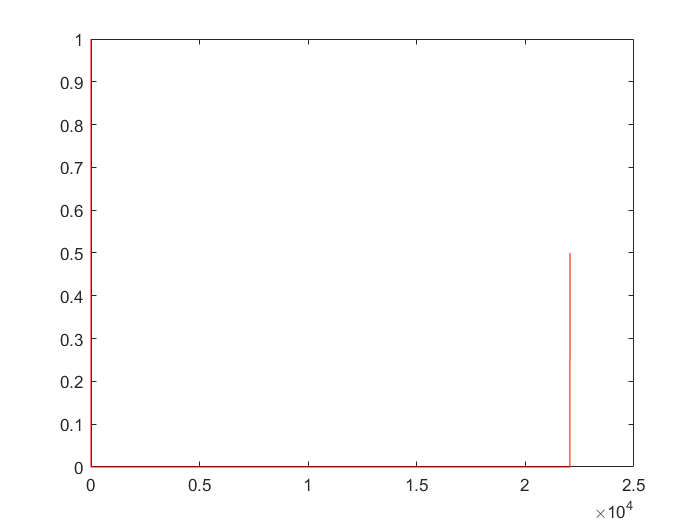

impulse = 1:1;
H_n = myEcho(impulse, alpha, n0);
plot(H_n, 'r')

Four :

echoed_voice = conv(voice, H_n);
sound(echoed_voice, sampling_freq)

It has echoed ! ! !

Five :

For finding n0, we use colerration concept. Suppose we have y; Then we move x on t-axis to measure colerration between x and that part of y (the part we have shifted x). for the first peak, we shall get t=0; Because there is a x[n] term in echo system that effect y[n]. for the second peak, we should get t=n0; Because the second term in system is x[n-n0]. so that part of y[n] must have most colerration than other near parts.(it might not be 0 and n0 but the difference must be n0). The idea of colerration can be implemented with convolution. we simply use conv(x[-n], y[n]) to find the peaks. the difference of the times that peaks occured, is n0

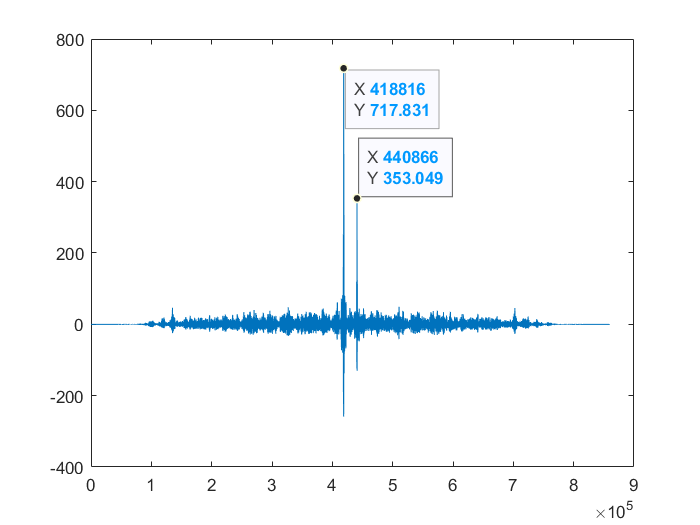

colerration = conv(flip(voice), echoed_voice);
plot(colerration)

ax = gca;
chart = ax.Children(1);
datatip(chart,4.188e+05,717.8);
ax2 = gca;
chart2 = ax2.Children(1);
datatip(chart2,4.409e+05,353);

n0 = 440866 - 418816 = 22050

Implementation of myConv function(Part1)

We assume that boundary of n for arguments is 1<= n <=length_of_argument and out side of this boundary values are zero.

function z = myConv(x, y)
    x_S = length(x);
    y_S = length(y);
    X = [x, zeros(1,y_S)];
    Y = [y, zeros(1,x_S)];
    output = zeros(1, x_S+y_S-1);
    for n = 1:x_S+y_S-1
        for m = 1:n
            if(n-m+1>0)
            output(n)=output(n)+X(m)*Y(n-m+1);
            end
        end
    end
    if(nargout==1)
        z = output;
    else
        hold off
        plot(1:x_S+y_S, output, 'b--o')
    end
end

Implementation of echo-system of Part3 

function y = myEcho(x, alpha, n0)
    X = [x zeros(1,n0)];
    shifted_X = [zeros(1,n0) x];
    shifted_X = shifted_X * alpha;
    y = X + shifted_X;
end